# Modifying Axes

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

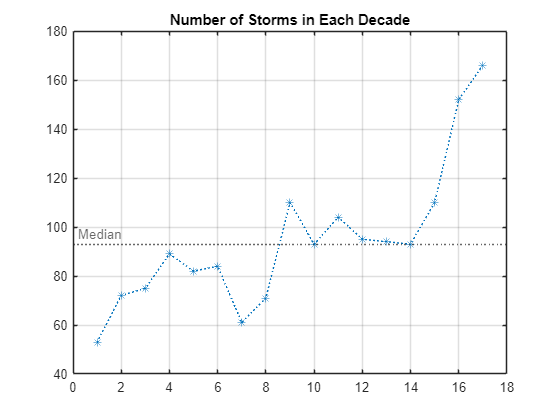

decades = [ "[1850, 1860)";
            "[1860, 1870)";
            "[1870, 1880)";
            "[1880, 1890)";
            "[1890, 1900)";
            "[1900, 1910)";
            "[1910, 1920)";
            "[1920, 1930)";
            "[1930, 1940)";
            "[1940, 1950)";
            "[1950, 1960)";
            "[1960, 1970)";
            "[1970, 1980)";
            "[1980, 1990)";
            "[1990, 2000)";
            "[2000, 2010)";
            "[2010, 2020)"];
numEvents = [53; 72; 75; 89; 82; 84; 61; 71; 110; 93; 104; 95; 94; 93; 110; 152];
the2010s = 166;
p = plot(numEvents);
p.LineStyle = ":";
p.Marker = "*";
p.YData(end+1) = the2010s;
med = median(p.YData);
y = yline(med, ":", "Median");
y.LabelHorizontalAlignment = "left";
grid on
title("Number of Storms in Each Decade")

## Task 1

Recall that you can obtain a handle to an axes object that has already been created with the `gca` command.

`a` `=` `gca`

Then you can access and modify properties of axes objects with dot notation, just like did with line properties.

`var` `=` `a.PropertyName`

`a.PropertyName` `=` `newVal`

ax = gca

ax =   Axes (Number of Storms in Each Decade) with properties:

             XLim: [0 18]
             YLim: [40 180]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


xt = ax.XTick

xt =      0     2     4     6     8    10    12    14    16    18


## Task 2

The variable `decades` contains a list of the decades for which you have plotted data. You can change the ticks on the x-axis with the `xticks` function.

`xticks``(``vec``)`

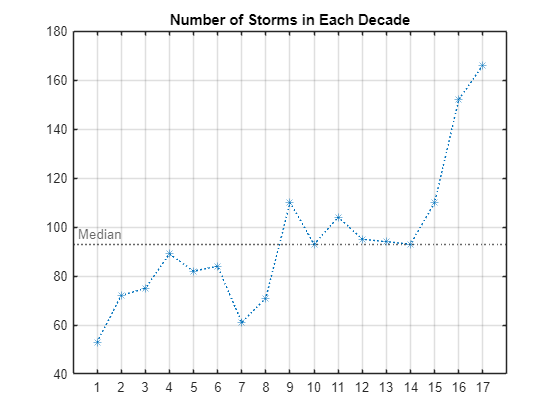

xticks(1:length(decades))

xt2 = ax.XTick

xt2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17


## Task 3

When you use a function like `xticks`, it sets one or more graphics properties. If you don't remember a specific function, you can scroll through the properties by starting to type the command. This can also help you discover new properties.

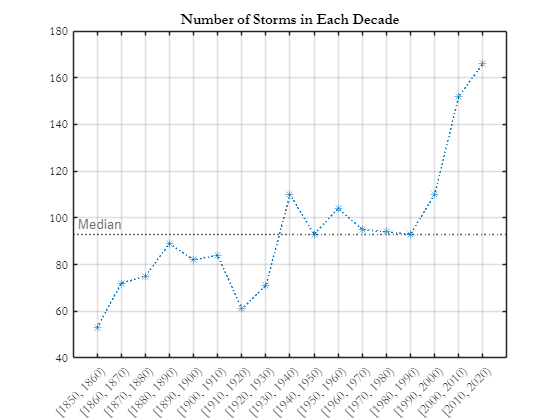

ax =   Axes (Number of Storms in Each Decade) with properties:

             XLim: [0 18]
             YLim: [40 180]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1445 0.7750 0.7805]
            Units: 'normalized'

  Show all properties


ax.XTickLabels = decades;  
ax.FontName = "Garamond"

## Task 4

Some functions accept graphics objects as inputs. For instance, to change the font size for all the text on the axes, you need to specify the axes object.

`fontsize``(``a``,``decrIncr``)`

The first input is a variable to a graphics object and the second one is either `"increase"` or `"decrease"`.

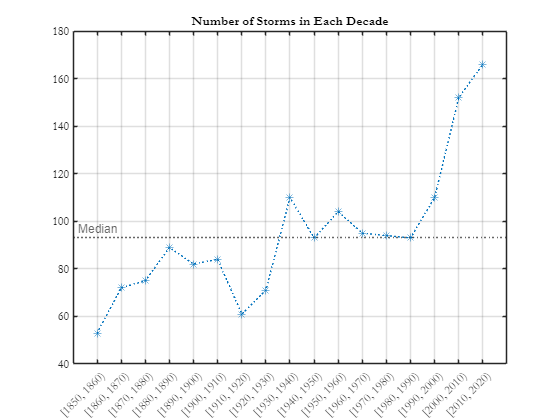

fontsize(ax, "decrease")

## Task 5

As with the other functions, there is a property of the axes that controls the font size. Try scrolling through the properties of `ax` to identify which one controls the font size.

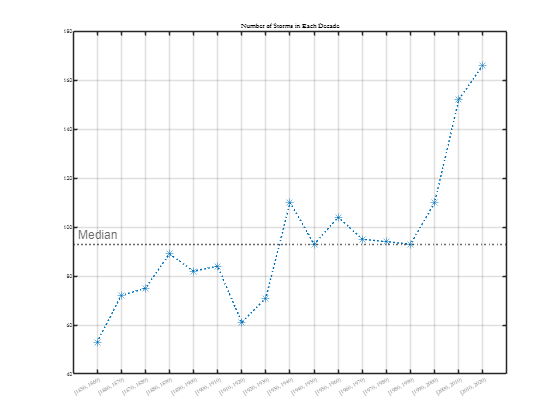

fs = ax.FontSize;
ax.FontSize = fs/2;

## Task 6

Some properties, like the one that controls the ratio of font sizes between the title and axes labels, do not have an associated function.

The x-axis labels are more spaced out, but now the title is a bit small. To adjust this parameter, you can modify the `TitleFontSizeMultiplier` property.

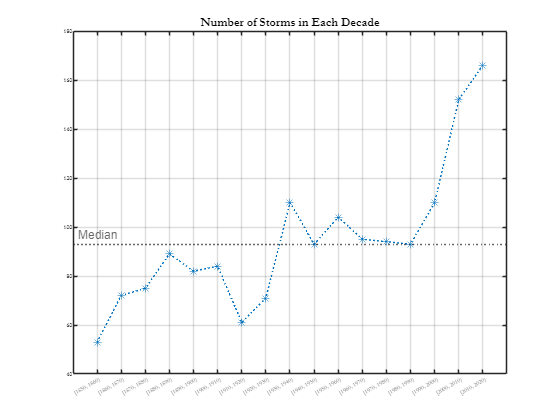

ax.TitleFontSizeMultiplier = 2;